brake = 100;
throttle = 50;
inputs = [brake throttle];

c = bar(X,[100,100],'FaceColor','flat')

c =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: 'flat'
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [Brake    Throttle]
        YData: [100 100]

  Show all properties


c(1).CData = [1 1 1; 1 1 1];

hold on

X = categorical({'Brake','Throttle'});
b = bar(X,inputs,'FaceColor','flat')

b =   Bar with properties:

    BarLayout: 'grouped'
     BarWidth: 0.8000
    FaceColor: 'flat'
    EdgeColor: [0 0 0]
    BaseValue: 0
        XData: [Brake    Throttle]
        YData: [100 50]

  Show all properties


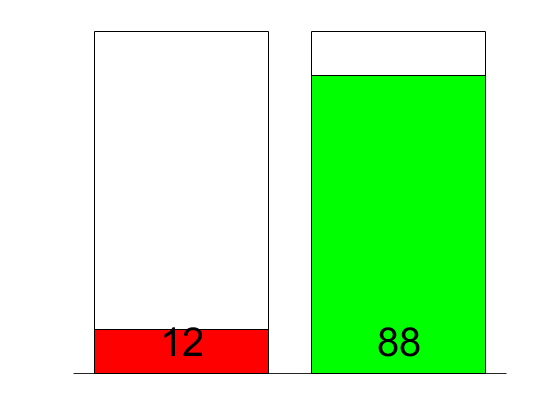

b.YDataSource = 'inputs';

b(1).CData = [1 0 0; 0 1 0];
ylim([0 100])
ax = gca;
disableDefaultInteractivity(ax)
axis off

% hFigure = figure;
% set(hFigure, 'MenuBar', 'none');
% set(hFigure, 'ToolBar', 'none');

xtips2 = b(1).XEndPoints;
%ytips2 = b(1).YEndPoints;
ytips2 = [10 10];
labels2 = string(b(1).YData);
label = text(xtips2,ytips2,labels2,'HorizontalAlignment','center','FontSize',30);



for i = 1:100
    inputs = [i 100-i];
    refreshdata
    drawnow
    pause(1/60);
    delete(label);
    labels2 = string(b(1).YData);
    label = text(xtips2,ytips2,labels2,'HorizontalAlignment','center','FontSize',30);
end



function updateData
    
end


%b(2).CData = [0 0 1];
